# Template of Manipulator Short project: Skull tumor surgery

Authors: 

Team:  

Shared Link with the teacher: 

Remember use the options of serial/link plot: 

'workspace' for centering in the surgery task

'zoom' ...  nice puma ratio aspect

'trail'  .. to see the trajectory

etc..

See all at:

>> help SerialLink/plot

## The Robotic environment (10%)

Think that later on the enviroment will move to any place in a Univers Reference Frame {U}

Use: 'c = uisetcolor' to chose your prefered colors

### Operating table.

 It can be raised, lowered, and tilted in any direction, and an  auxiliary table for the tools. Define: Vertices and Faces and use  'patch'  functions to model it. See help patch to find and example.

**Expected results**

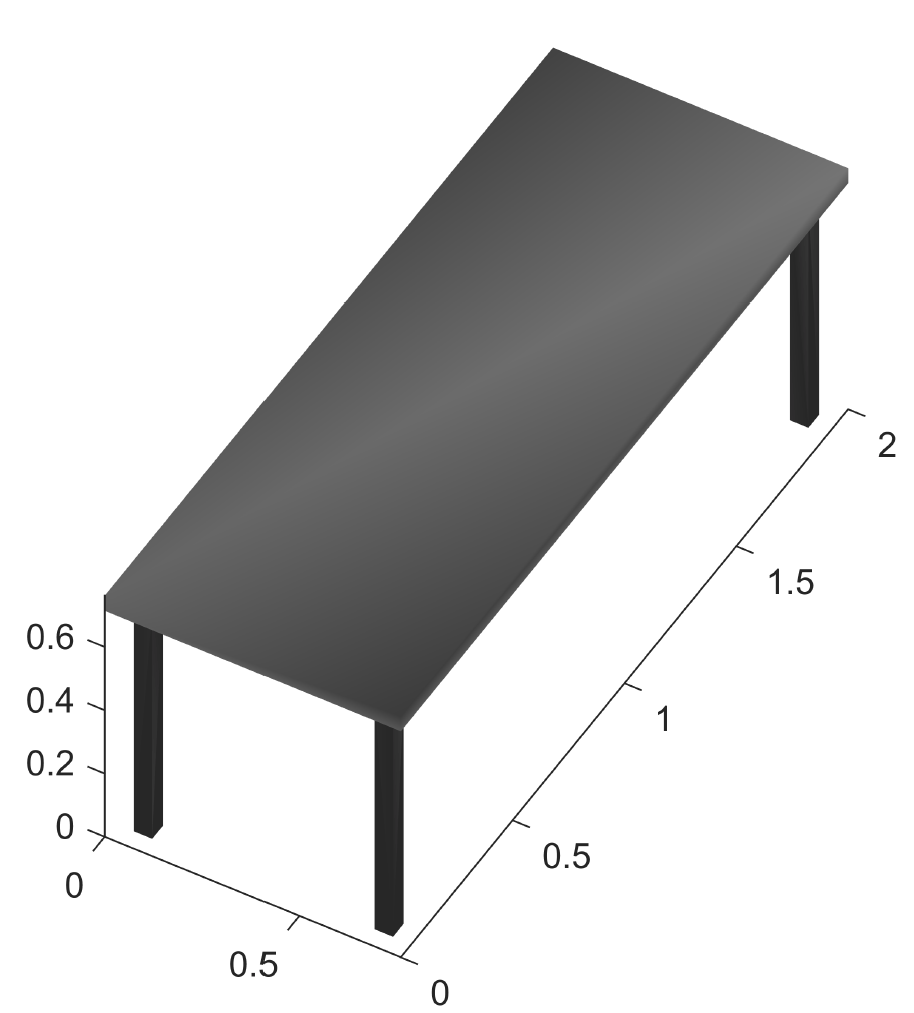

DIBUIXEM SOLS LA TAULA PRIMER

clear all
close all
clf
v= [0 0 0;1 0 0;1 1 0;0 1 0;0 0 1;1 0 1;1 1 1;0 1 1]

v =      0     0     0
     1     0     0
     1     1     0
     0     1     0
     0     0     1
     1     0     1
     1     1     1
     0     1     1


f = [1 2 6 5;2 3 7 6;3 4 8 7;4 1 5 8;1 2 3 4;5 6 7 8]

f =      1     2     6     5
     2     3     7     6
     3     4     8     7
     4     1     5     8
     1     2     3     4
     5     6     7     8


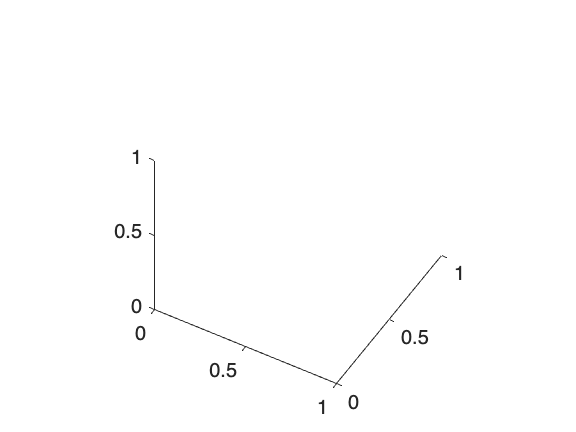

view(30,45)
axis equal

H=2

H = 2

W=0.9

W = 0.9000

D=0.08

D = 0.0800

v_taula=[H 0 0;0 W 0;0 0 D]*v'

v_taula =          0    2.0000    2.0000         0         0    2.0000    2.0000         0
         0         0    0.9000    0.9000         0         0    0.9000    0.9000
         0         0         0         0    0.0800    0.0800    0.0800    0.0800


%patch('Vertices',v_taula','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','r','FaceAlpha',0.3)

### 3D model of a human body 

Situate the human model on the operating table. 

Use: F_V_HumanBody.mat as a model

**Expected results**

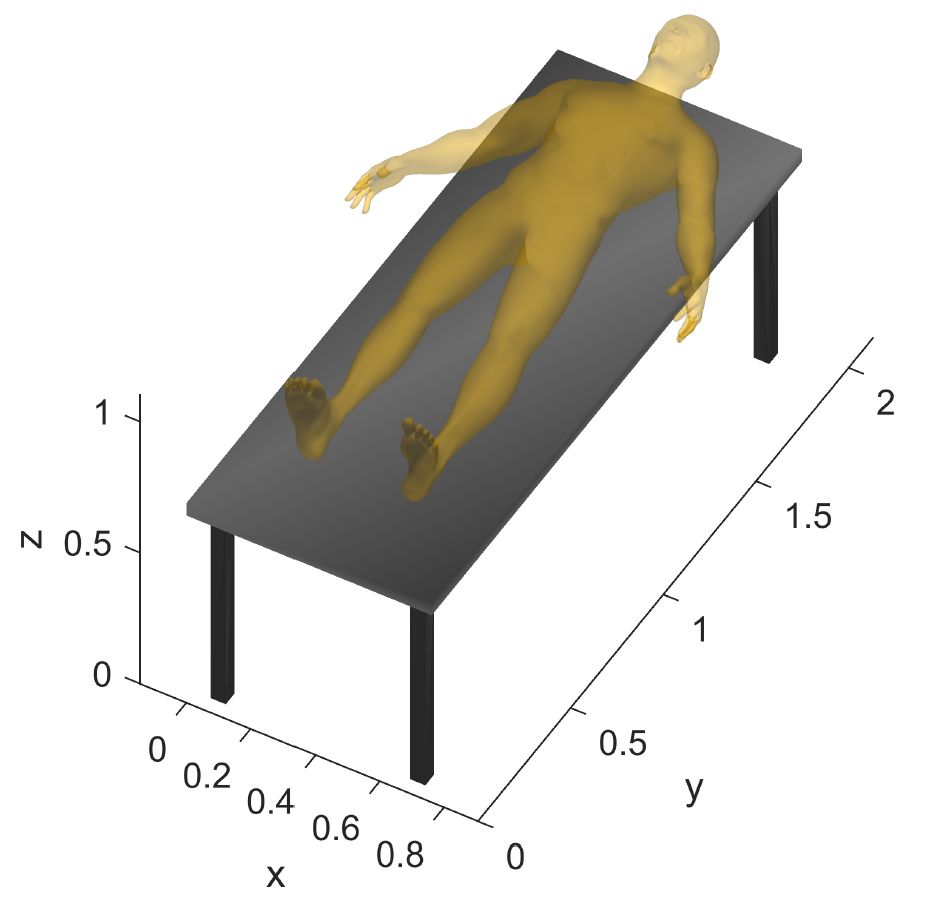

DIBUIXEM  L'HUMÀ DEVORA LA TAULA

%HB = load('F_V_HumanBody.mat')
%H=1.1 % x
%W=0.4 % y
%v_h_0=[H 0 0;0 W 0;0 0 D]*HB.Vh'
%T_huma_0=transl(0.25,0.5,0.2)*trotz(-pi/2)*trotx(-pi/2) %huma
%v_h_0(4,:)=1
%v_h=T_huma_0*v_h_0

%v_taula = v_1

%patch('Vertices',v_taula','Faces',f,'FaceVertexCData',hsv(6),'FaceColor',[0.8 0.8 0.8],'EdgeColor','none','FaceLighting', 'gouraud','AmbientStrength', 0.8,'FaceAlpha', 0.3)
%patch('Faces', HB.Fh, 'Vertices', v_h(1:3,:)', 'FaceColor',[0.8 0.8 1.0],'EdgeColor','none','FaceLighting', 'gouraud','AmbientStrength', 0.8,'FaceAlpha', 0.8);
%axis([-0.5 0.5 -0.5 0.5 -0.5 2])
%camlight('headlight');
%material('dull');
%axis equal

ROTACIONS + TRANSLACIONS

ara li farem les rotacions i translacions necessàries perque quan moguem la taula es mogui l'huma


hold on
%humà
HB = load('F_V_HumanBody.mat')

HB = struct with fields:
    Fh: [48918×3 double]
    Vh: [24461×3 double]


H=1.1 % x

H = 1.1000

W=0.4 % y

W = 0.4000

D=1.1 % z

D = 1.1000

v_h_0=[H 0 0;0 W 0;0 0 D]*HB.Vh' %l'humà a la pos inicial

v_h_0 =    -0.1258   -0.1395   -0.1310   -0.1218   -0.1261   -0.1191   -0.1360   -0.1278   -0.1393   -0.1298   -0.1416   -0.1317   -0.1190   -0.1199   -0.1092   -0.1213   -0.1104   -0.1231   -0.1120   -0.1253   -0.1142   -0.1278   -0.1170   -0.1027   -0.1005   -0.1056   -0.1378   -0.1405   -0.1311   -0.1356   -0.1205   -0.1336   -0.1434   -0.1450   -0.0988   -0.0979   -0.0857   -0.0975   -0.0860   -0.1088   -0.0980   -0.1092   -0.0861   -0.0870   -0.0751   -0.0742   -0.0739   -0.1109   -0.1009   -0.1133
    0.0573    0.0554    0.0580    0.0590    0.0593    0.0602    0.0581    0.0597    0.0585    0.0601    0.0590    0.0605    0.0608    0.0614    0.0624    0.0618    0.0628    0.0621    0.0630    0.0622    0.0630    0.0621    0.0627    0.0636    0.0637    0.0631    0.0613    0.0611    0.0617    0.0612    0.0621    0.0609    0.0596    0.0600    0.0636    0.0633    0.0634    0.0628    0.0639    0.0619    0.0621    0.0612    0.0627    0.0642    0.0644    0.0641    0.0636    0.0601    0.0600 


T_huma_0=transl(0.2,0.4,0.2)*trotz(-pi/2)*trotx(-pi/2) %huma rotat

T_huma_0 =          0         0    1.0000    0.2000
   -1.0000         0         0    0.4000
         0   -1.0000         0    0.2000
         0         0         0    1.0000


v_h_0(4,:)=1

v_h_0 =    -0.1258   -0.1395   -0.1310   -0.1218   -0.1261   -0.1191   -0.1360   -0.1278   -0.1393   -0.1298   -0.1416   -0.1317   -0.1190   -0.1199   -0.1092   -0.1213   -0.1104   -0.1231   -0.1120   -0.1253   -0.1142   -0.1278   -0.1170   -0.1027   -0.1005   -0.1056   -0.1378   -0.1405   -0.1311   -0.1356   -0.1205   -0.1336   -0.1434   -0.1450   -0.0988   -0.0979   -0.0857   -0.0975   -0.0860   -0.1088   -0.0980   -0.1092   -0.0861   -0.0870   -0.0751   -0.0742   -0.0739   -0.1109   -0.1009   -0.1133
    0.0573    0.0554    0.0580    0.0590    0.0593    0.0602    0.0581    0.0597    0.0585    0.0601    0.0590    0.0605    0.0608    0.0614    0.0624    0.0618    0.0628    0.0621    0.0630    0.0622    0.0630    0.0621    0.0627    0.0636    0.0637    0.0631    0.0613    0.0611    0.0617    0.0612    0.0621    0.0609    0.0596    0.0600    0.0636    0.0633    0.0634    0.0628    0.0639    0.0619    0.0621    0.0612    0.0627    0.0642    0.0644    0.0641    0.0636    0.0601    0.0600 

v_h=T_huma_0*v_h_0

v_h =     1.6421    1.6464    1.6561    1.6527    1.6618    1.6615    1.6635    1.6679    1.6719    1.6761    1.6807    1.6850    1.6700    1.6792    1.6820    1.6889    1.6925    1.6987    1.7031    1.7085    1.7139    1.7181    1.7245    1.7194    1.7076    1.7311    1.7120    1.7198    1.7271    1.7034    1.7347    1.6943    1.6896    1.6983    1.6960    1.6846    1.6750    1.6734    1.6871    1.6717    1.6621    1.6616    1.6629    1.6994    1.7025    1.6893    1.6765    1.6512    1.6388    1.6398
    0.5258    0.5395    0.5310    0.5218    0.5261    0.5191    0.5360    0.5278    0.5393    0.5298    0.5416    0.5317    0.5190    0.5199    0.5092    0.5213    0.5104    0.5231    0.5120    0.5253    0.5142    0.5278    0.5170    0.5027    0.5005    0.5056    0.5378    0.5405    0.5311    0.5356    0.5205    0.5336    0.5434    0.5450    0.4988    0.4979    0.4857    0.4975    0.4860    0.5088    0.4980    0.5092    0.4861    0.4870    0.4751    0.4742    0.4739    0.5109    0.5009   



%transformacions taula
T_taula=transl(10,8,0.8)*trotz(pi/6) %taula

T_taula =     0.8660   -0.5000         0   10.0000
    0.5000    0.8660         0    8.0000
         0         0    1.0000    0.8000
         0         0         0    1.0000


v_taula(4,:)=1

v_taula =          0    2.0000    2.0000         0         0    2.0000    2.0000         0
         0         0    0.9000    0.9000         0         0    0.9000    0.9000
         0         0         0         0    0.0800    0.0800    0.0800    0.0800
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


v_t_0 = T_taula*v_taula

v_t_0 =    10.0000   11.7321   11.2821    9.5500   10.0000   11.7321   11.2821    9.5500
    8.0000    9.0000    9.7794    8.7794    8.0000    9.0000    9.7794    8.7794
    0.8000    0.8000    0.8000    0.8000    0.8800    0.8800    0.8800    0.8800
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000



%transformacions huma perque vagi amb la taula
T_huma_taula=T_taula*T_huma_0 %huma - taula

T_huma_taula =     0.5000         0    0.8660    9.9732
   -0.8660         0    0.5000    8.4464
         0   -1.0000         0    1.0000
         0         0         0    1.0000


v_h_1=T_huma_taula*v_h_0

v_h_1 =    11.1592   11.1561   11.1688   11.1704   11.1761   11.1794   11.1726   11.1805   11.1783   11.1866   11.1848   11.1934   11.1868   11.1943   11.2020   11.2019   11.2105   11.2096   11.2189   11.2170   11.2271   11.2240   11.2349   11.2377   11.2286   11.2464   11.2137   11.2191   11.2302   11.2074   11.2420   11.2005   11.1915   11.1983   11.2194   11.2100   11.2077   11.2004   11.2181   11.1934   11.1905   11.1844   11.1970   11.2283   11.2368   11.2259   11.2149   11.1745   11.1688   11.1635
    9.2764    9.2904    9.2879    9.2782    9.2865    9.2803    9.2960    9.2910    9.3030    9.2969    9.3094    9.3030    9.2845    9.2898    9.2820    9.2959    9.2882    9.3024    9.2950    9.3092    9.3023    9.3162    9.3100    9.2950    9.2872    9.3034    9.3217    9.3280    9.3234    9.3155    9.3181    9.3093    9.3154    9.3211    9.2800    9.2735    9.2582    9.2676    9.2645    9.2765    9.2623    9.2718    9.2525    9.2714    9.2627    9.2554    9.2487    9.2681    9.2532 

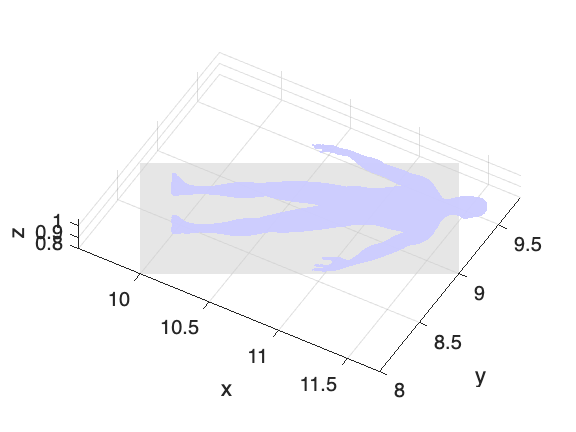



%perque dibuixi la taula i l'huma ja girats
patch('Vertices',v_t_0(1:3, :)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor',[0.8 0.8 0.8],'EdgeColor','none','FaceLighting', 'gouraud','AmbientStrength', 0.8,'FaceAlpha', 0.3)
patch('Faces', HB.Fh, 'Vertices', v_h_1(1:3,:)', 'FaceColor',[0.8 0.8 1.0],'EdgeColor','none','FaceLighting', 'gouraud','AmbientStrength', 0.8,'FaceAlpha', 0.8);
material('dull');
axis equal
view(30,45)
grid on
xyzlabel
axis equal

%axis([-1.5 1.5 -1.5 3.5 -0.5 2.5])
%surf(X*r+Point_U(1),Y*r+Point_U(2),Z*r+Point_U(3),'FaceColor',[1 0 0])

### Dicom image vs Image Reference frame {I}

Get familiar with Dicom Images and the functionalities of the viewer, Visit: https://www.dicomlibrary.com

Infer the Image Reference Frame {I} and the skull containig box dimensions.

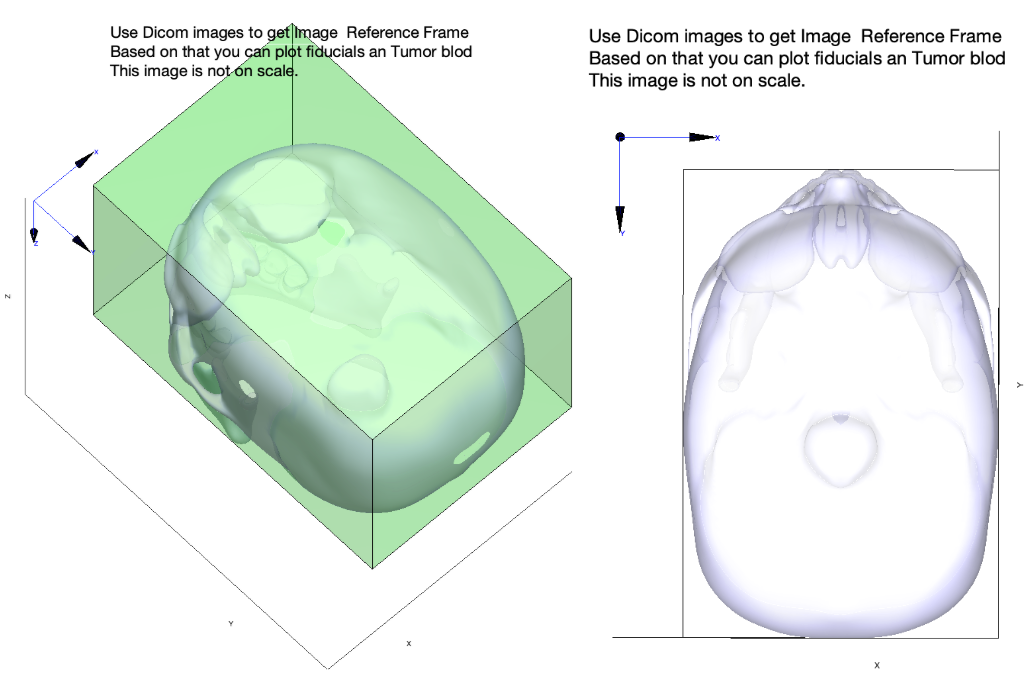

### Fiducials wrt {I}

The Radiology Department before to take a Computer Tomography (CT) of the brain, fix three fiducials in the head of the patient for registering purpose,  visit: [https://en.wikipedia.org/wiki/Fiducial](https://en.wikipedia.org/wiki/Fiducial)

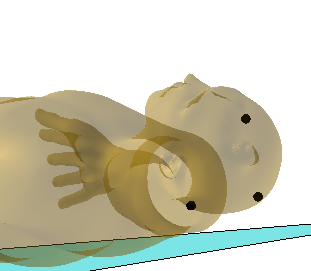

Use the Dicom images to obtain the fiducial coordinates relative to Image Reference Frame {I}.

**Expected results**

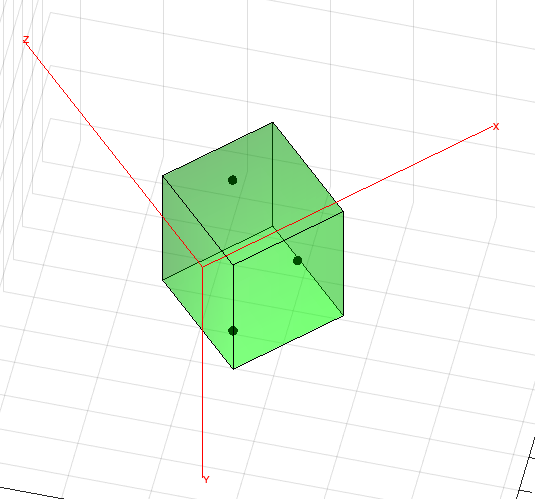

dibuixi sols els fidurals

hold on
H = 0.15

H = 0.1500

W = 0.20

W = 0.2000

D = 0.17

D = 0.1700

v_c= [0 0 0;1 0 0;1 1 0;0 1 0;0 0 1;1 0 1;1 1 1;0 1 1]

v_c =      0     0     0
     1     0     0
     1     1     0
     0     1     0
     0     0     1
     1     0     1
     1     1     1
     0     1     1


v_box = [H 0 0; 0 W 0; 0 0 D]*v_c'

v_box =          0    0.1500    0.1500         0         0    0.1500    0.1500         0
         0         0    0.2000    0.2000         0         0    0.2000    0.2000
         0         0         0         0    0.1700    0.1700    0.1700    0.1700


f_box = [1 2 6 5;2 3 7 6;3 4 8 7;4 1 5 8;1 2 3 4;5 6 7 8]

f_box =      1     2     6     5
     2     3     7     6
     3     4     8     7
     4     1     5     8
     1     2     3     4
     5     6     7     8



%v_box = [41.26 214.76 0;190.37 214.76 0;190.37 32.82 0;41.26 32.82 0;41.26 214.76 156.8;190.37 214.76 156.8;190.37 32.82 156.8;41.26 32.82 156.8]

%patch('Vertices',v_box_1(1:3, :)','Faces',f_box,'FaceVertexCData',hsv(6),'FaceColor',[0.9 0.9 0.5],'FaceAlpha',0.3)
%view(30,45)
%axis equal

ara unirem tot el que ja teniem abans (sense fidurals)

T_box_huma = transl(-0.08,-0.12,1.82)

T_box_huma =     1.0000         0         0   -0.0800
         0    1.0000         0   -0.1200
         0         0    1.0000    1.8200
         0         0         0    1.0000


T_box_0 = T_huma_taula*T_box_huma

T_box_0 =     0.5000         0    0.8660   11.5094
   -0.8660         0    0.5000    9.4257
         0   -1.0000         0    1.1200
         0         0         0    1.0000


v_box(4, :) = 1

v_box =          0    0.1500    0.1500         0         0    0.1500    0.1500         0
         0         0    0.2000    0.2000         0         0    0.2000    0.2000
         0         0         0         0    0.1700    0.1700    0.1700    0.1700
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


v_box_1 = T_box_0*v_box

v_box_1 =    11.5094   11.5844   11.5844   11.5094   11.6566   11.7316   11.7316   11.6566
    9.4257    9.2958    9.2958    9.4257    9.5107    9.3808    9.3808    9.5107
    1.1200    1.1200    0.9200    0.9200    1.1200    1.1200    0.9200    0.9200
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


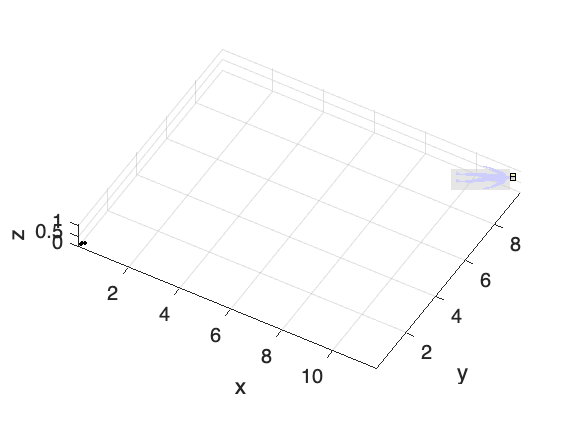

patch('Vertices',v_t_0(1:3, :)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor',[0.8 0.8 0.8],'EdgeColor','none','FaceLighting', 'gouraud','AmbientStrength', 0.8,'FaceAlpha', 0.3)
patch('Faces', HB.Fh, 'Vertices', v_h_1(1:3,:)', 'FaceColor',[0.8 0.8 1.0],'EdgeColor','none','FaceLighting', 'gouraud','AmbientStrength', 0.8,'FaceAlpha', 0.8);
patch('Vertices',v_box_1(1:3, :)','Faces',f_box,'FaceVertexCData',hsv(6),'FaceColor',[0.9 0.9 0.5],'FaceAlpha',0.3)

material('dull');
axis equal
view(30,45)
grid on
xyzlabel
axis equal

hold on
[X,Y,Z] = sphere;
r = 0.005;
surf(X*r+0.066,Y*r+0.197,Z*r+0.044,'FaceColor',[1 0 0])
axis equal
[X2,Y2,Z2] = sphere;
X2 = X * r;
Y2 = Y * r;
Z2 = Z * r; 
surf(X2+0.173,Y2+0.196,Z2+0.091,'FaceColor',[0 1 0])
axis equal
[X3,Y3,Z3] = sphere;
X3 = X * r;
Y3 = Y * r;
Z3 = Z * r; 
surf(X3+0.114,Y3+0.056,Z3+0.131,'FaceColor',[0 0 1])
axis equal

### Tumor points wrt {I}

Use the Dicom images to get the points of the outer perimeter of the tumor relative to Image Reference Frame {I}.

You can simplify the tumor information by defining the center of mass and estimate an equivalent diameter.

**Expected results**

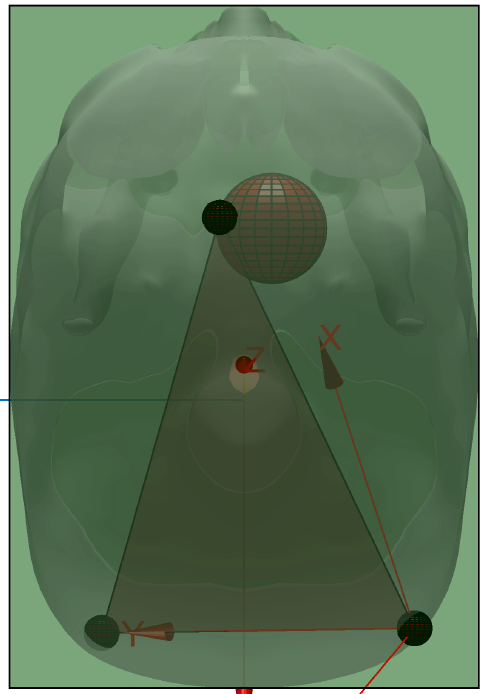

### Fiducials and Tumor wrt Human Reference Frame

Place fiducial and tumor in the head of the human. 

**Expected results**

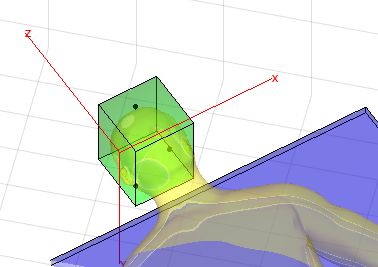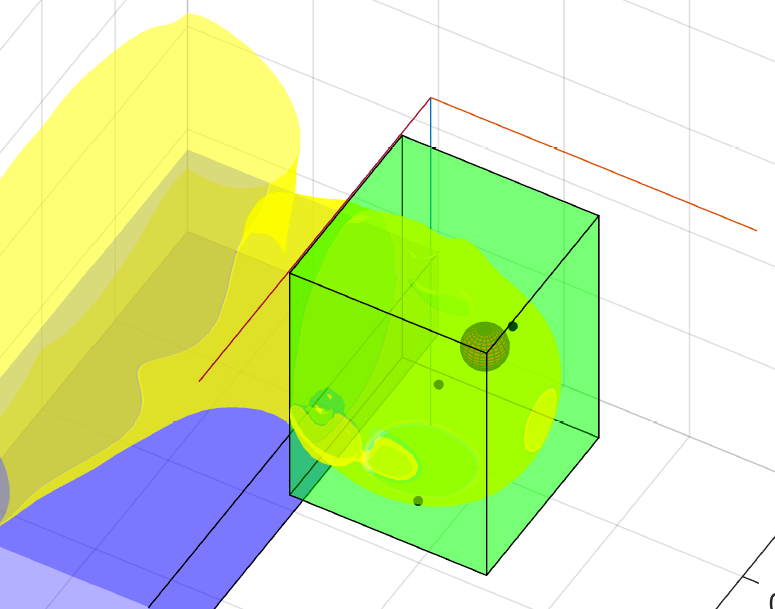

### Reference Frames

Display all necessary reference frame. Use best scale to see it.

- {U} Univers [0 0 0]

- {R} Robot

- {I} Image

- {Tb} Table_body

- {Tt} Table tool

- {EE} End Efector

- others

- ...